## Gabriel Werpel Fernandes

## June 2024

## Load Data

% Close all figures and clear variables
clc;
close all;
clearvars;

%Process EEG Data
data = processAllEEGData();

Data for file A1_Full_Block.bdf processed successfully
Data for file A3_Full_Block.bdf processed successfully
Data for file A4_Full_Block.bdf processed successfully
Data for file A6_Alpha.bdf processed successfully
Data for file A7_Alpha.bdf processed successfully
Data for file A8_Alpha.bdf processed successfully
Data for file A9_Alpha.bdf processed successfully
Data for file C11_Alpha.bdf processed successfully
Data for file C12_Alpha.bdf processed successfully
Data for file C13_Alpha.bdf processed successfully
Data for file C14_Alpha.bdf processed successfully
Data for file C15_Alpha.bdf processed successfully
Data for file C1_Alpha.bdf processed successfully


## Plot Time-Series

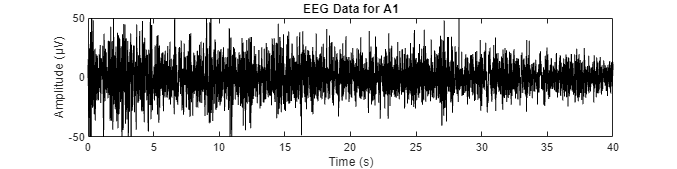

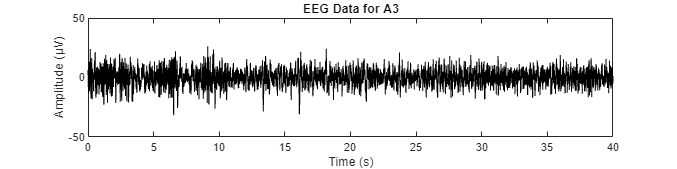

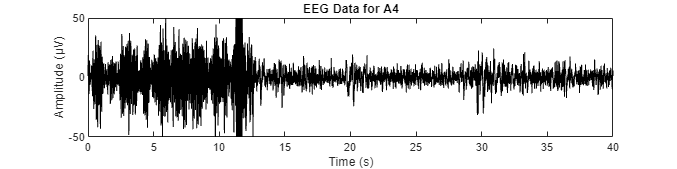

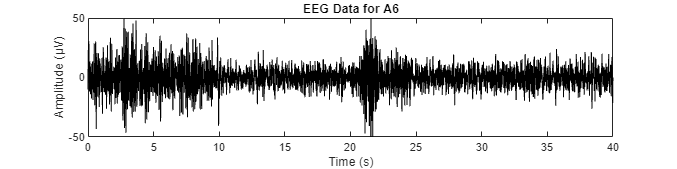

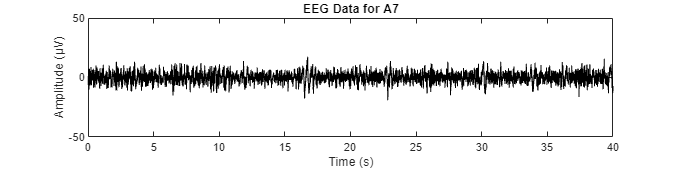

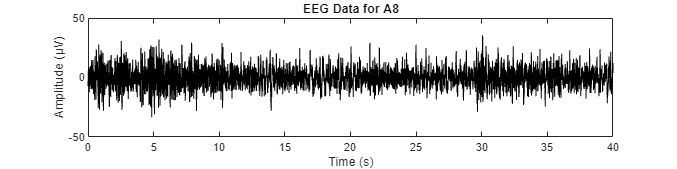

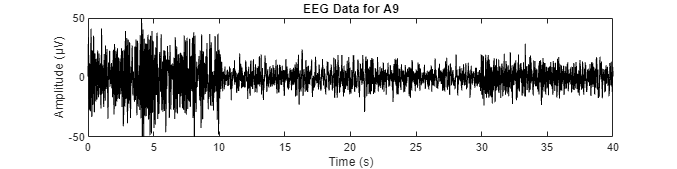

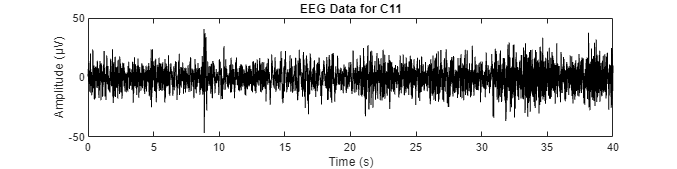

% Plot all EEG data
plotAllEEGData(data);

## Segment Data

% Segment the EEG data
segmentedData = segmentEEGDataNew2s(data);

## Time-Domain Analysis

### Statistical Measures: Mean, Variance, Std. Deviation, Skewness and Kurtosis

% Calculate and display the extended statistics for all keys and sections
extendedStatisticsResults = calculateExtendedStatisticsForAllSections(segmentedData);

      Key             Section             DataType      Mean      Variance    StandardDeviation    Skewness    Kurtosis
    _______    ______________________    __________    _______    ________    _________________    ________    ________

    {'A1' }    {'EC'                }    {'Normal'}     -0.075     299.23           17.298           0.145       3.368 
    {'A1' }    {'EO'                }    {'Normal'}      0.036     131.54           11.469             0.2       3.625 
    {'A1' }    {'DEC'               }    {'Normal'}     -0.031     109.56           10.467           0.282       4.004 
    {'A1' }    {'NDEC'              }    {'Normal'}     -0.002     68.451            8.274           0.054       3.052 
    {'A

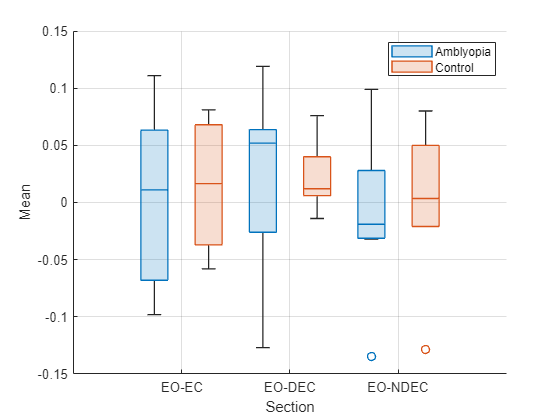

% Load the data
data = readtable('TableA.1.1.csv');

% Call the function for each metric
plotBoxChart(data, 'Mean', 'Mean');

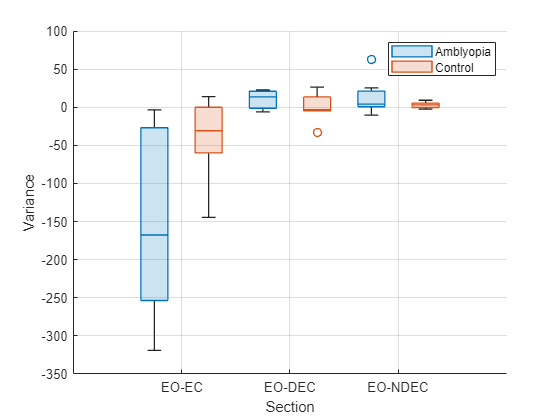

plotBoxChart(data, 'Variance', 'Variance');

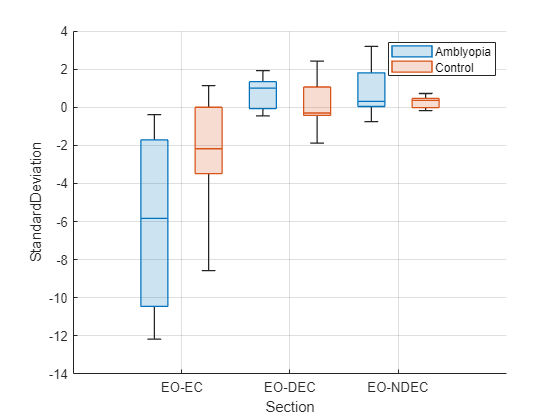

plotBoxChart(data, 'StandardDeviation', 'Standard Deviation');

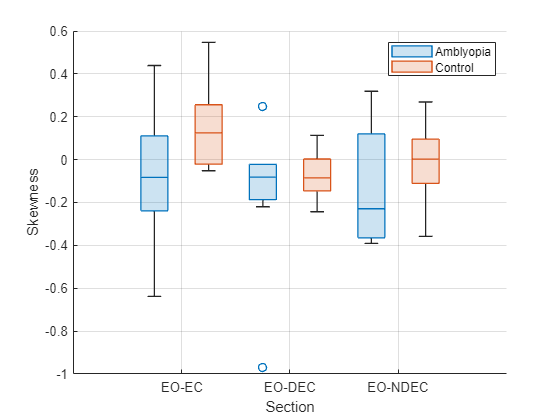

plotBoxChart(data, 'Skewness', 'Skewness');

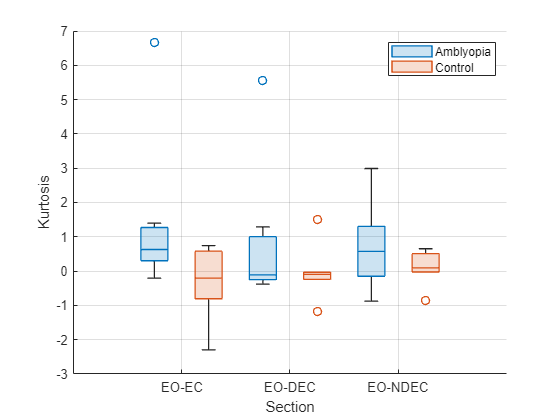

plotBoxChart(data, 'Kurtosis', 'Kurtosis');

calculateStatisticalDifferences(data, 'Mean');

Pairwise Statistical Analysis for Mean:
EO-EC vs EO-DEC: p-value = 0.8575
EO-EC vs EO-NDEC: p-value = 0.6081
EO-DEC vs EO-NDEC: p-value = 0.1998


calculateStatisticalDifferences(data, 'Variance');

Pairwise Statistical Analysis for Variance:
EO-EC vs EO-DEC: p-value = 0.0012
EO-EC vs EO-NDEC: p-value = 0.0005
EO-DEC vs EO-NDEC: p-value = 0.7196


calculateStatisticalDifferences(data, 'StandardDeviation');

Pairwise Statistical Analysis for StandardDeviation:
EO-EC vs EO-DEC: p-value = 0.0010
EO-EC vs EO-NDEC: p-value = 0.0005
EO-DEC vs EO-NDEC: p-value = 0.7438


calculateStatisticalDifferences(data, 'Skewness');

Pairwise Statistical Analysis for Skewness:
EO-EC vs EO-DEC: p-value = 0.1370
EO-EC vs EO-NDEC: p-value = 0.3560
EO-DEC vs EO-NDEC: p-value = 0.9183


calculateStatisticalDifferences(data, 'Kurtosis');

Pairwise Statistical Analysis for Kurtosis:
EO-EC vs EO-DEC: p-value = 0.8361
EO-EC vs EO-NDEC: p-value = 0.7884
EO-DEC vs EO-NDEC: p-value = 0.9737


calculateGroupStatisticalDifferences(data, 'Variance');

Group Statistical Analysis for Variance (Amblyopia vs Control):
EO-EC (Amblyopia vs Control): p-value = 0.1375
EO-DEC (Amblyopia vs Control): p-value = 0.3660
EO-NDEC (Amblyopia vs Control): p-value = 0.5338


calculateGroupStatisticalDifferences(data, 'StandardDeviation');

Group Statistical Analysis for StandardDeviation (Amblyopia vs Control):
EO-EC (Amblyopia vs Control): p-value = 0.2343
EO-DEC (Amblyopia vs Control): p-value = 0.3565
EO-NDEC (Amblyopia vs Control): p-value = 0.3633
